## 2. Revisar la literatura del *Toolbox de Peter Corke.(RVC)*. Espec´ıficamente los **objetos Link**, **SerialLink** y los métodos de dichos objetos que proporcionan la cinemática directa e inversa.

### **Link**

**Robot manipulator Link class**

A Link object holds all information related to a robot link such as kinematics parameters, rigid-body inertial parameters, motor and transmission parameters.  

**Methods**  

A                             link transform matrix  

RP                          joint type: ‘R’ or ‘P’

friction                    friction force

nofriction Link         object with friction parameters set to zero  

dyn                         display link dynamic parameters  

islimit                      test if joint exceeds soft limit  

isrevolute                test if joint is revolute  

isprismatic              test if joint is prismatic  

display                    print the link parameters in human readable form  

char                         convert to string  

**Properties (read/write)**

theta                 kinematic: joint angle

d                     kinematic: link offset

a                         kinematic: link length

alpha                 kinematic: link twist

sigma                 kinematic: 0 if revolute, 1 if prismatic

mdh                 kinematic: 0 if standard D&H, else 1

offset                 kinematic: joint variable offset

qlim                 kinematic: joint variable limits [min max]

-----------------------------------------------------------------------------------------------------

m                     dynamic: link mass

r                     dynamic: link COG wrt link coordinate frame 3 *× *1

I                     dynamic: link inertia matrix, symmetric 3 *× *3, about link COG.

B                     dynamic: link viscous friction (motor referred)

Tc                 dynamic: link Coulomb friction

-------------------------------------------------------------------------------------------------------------

G                 actuator: gear ratio

Jm                 actuator: motor inertia (motor referred)

  **Examples**  

L = Link([0 1.2 0.3 pi/2])

 
L = 
 theta=q, d=        1.2, a=        0.3, alpha=      1.571, offset=          0 (R,stdDH)


%L = Link(%revolute’, ’d’, 1.2, ’a’, 0.3, ’alpha’, pi/2)
%L = Revolute(%d’, 1.2, ’a’, 0.3, ’alpha’, pi/2)

### **SerialLink**

**Serial-link robot class**

A concrete class that represents a serial-link arm-type robot. The mechanism is described using Denavit-Hartenberg parameters, one set per joint.  

**Methods**

plot 			display graphical representation of robot

plot3d 			display 3D graphical model of robot

teach 			drive the graphical robot

getpos 			get position of graphical robot

-----------------------------------------------------------------------------------------------

jtraj 			a joint space trajectory

-----------------------------------------------------------------------------------------------

edit 			display and edit kinematic and dynamic parameters

-----------------------------------------------------------------------------------------------

isspherical 		test if robot has spherical wrist

islimit 		test if robot at joint limit

isconfig 		test robot joint configuration

-----------------------------------------------------------------------------------------------

fkine 			forward kinematics

A 			link transforms

trchain 		forward kinematics as a chain of elementary transforms

-----------------------------------------------------------------------------------------------

ikine6s 		inverse kinematics for 6-axis spherical wrist revolute robot

ikine			inverse kinematics using iterative numerical method

ikunc			inverse kinematics using optimisation

ikcon			inverse kinematics using optimisation with joint limits

ikine_sym 		analytic inverse kinematics obtained symbolically

-----------------------------------------------------------------------------------------------

jacob0 			Jacobian matrix in world frame

jacobn 			Jacobian matrix in tool frame

jacob_dot 		Jacobian derivative

maniplty 		manipulability

vellipse 		display velocity ellipsoid

fellipse 		display force ellipsoid

qmincon 		null space motion to centre joints between limits

-----------------------------------------------------------------------------------------------

accel 			joint acceleration

coriolis 		Coriolis joint force

dyn 			show dynamic properties of links

friction 		friction force

gravload 		gravity joint force

inertia 		joint inertia matrix

cinertia 		Cartesian inertia matrix

nofriction 		set friction parameters to zero

rne 			inverse dynamics

fdyn 			forward dynamics

-----------------------------------------------------------------------------------------------

payload 		add a payload in end-effector frame

perturb 		randomly perturb link dynamic parameters

gravjac 		gravity load and Jacobian

paycap 			payload capacity

pay 			payload effect

-----------------------------------------------------------------------------------------------

sym 			a symbolic version of the object

gencoords 		symbolic generalized coordinates

genforces 		symbolic generalized forces

issym 			test if object is symbolic

**Properties (read/write)**  

links 			vector of Link objects (1 × N)

gravity 		direction of gravity [gx gy gz]

base 			pose of robot’s base (4 × 4 homog xform)

tool 			robot’s tool transform, T6 to tool tip (4 × 4 homog xform)

qlim 			joint limits, [qmin qmax] (N × 2)

offset 			kinematic joint coordinate offsets (N × 1)

name 			name of robot, used for graphical display

manuf 			annotation, manufacturer’s name

comment 		annotation, general comment

plotopt 		options for plot() method (cell array)

fast 			use MEX version of RNE. Can only be set true if the mex file exists. Default is true.

**Properties (read only)**  

n 			number of joints

config 			joint configuration string, eg. ‘RRRRRR’

mdh 			kinematic convention boolean (0=DH, 1=MDH)

theta 			kinematic: joint angles (1 × N)

d 			    kinematic: link offsets (1 × N)

a 			    kinematic: link lengths (1 × N)

alpha 			kinematic: link twists (1 × N)

**Overloaded operators**  

R1*R2             concatenate two SerialLink manipulators R1 and R2  

## 3.Para introducirse al manejo del *Robotics Systems Toolbox (RST) *de MATLAB® desarrolle el ejercicio *Build a Robot Step by Step *. Adem´as, revise las *funciones completas *del toolbox.  

### Construir un robot paso a paso

Este ejemplo pasa por el proceso de construcción de un robot paso a paso, mostrándole los diferentes componentes del robot y cómo se llama a las funciones para construirlo. Se muestran las secciones de código, pero los valores reales de las dimensiones y transformaciones dependen del robot.

- Cree un objeto de sólido

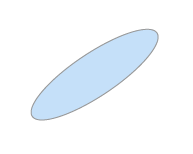

body1 = rigidBody('body1')

body1 =   rigidBody with properties:

            Name: 'body1'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


        2.Cree una unión y asígnela al sólido rígido. Defina la propiedad de posición de inicio de la junta, .`HomePosition` Establezca la transformación de unión a padre mediante una transformación homogénea, .`tform` Utilice la función para convertir de un vector de traducción a una transformación homogénea. se establece en una matriz de identidad.[`trvec2tform`](https://la.mathworks.com/help/robotics/ref/trvec2tform.html)`ChildToJointTransform`

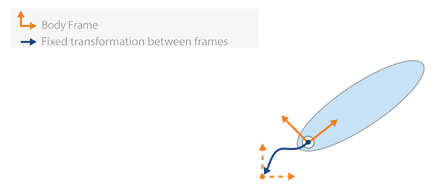

jnt1 = rigidBodyJoint('jnt1','revolute')

jnt1 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt1'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


jnt1.HomePosition = pi/4

jnt1 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt1'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0.7854
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform = trvec2tform([0.25, 0.25, 0])% User defined 

tform =     1.0000         0         0    0.2500
         0    1.0000         0    0.2500
         0         0    1.0000         0
         0         0         0    1.0000


setFixedTransform(jnt1,tform); 
body1.Joint = jnt1

body1 =   rigidBody with properties:

            Name: 'body1'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


    3.Cree un árbol de sólido rígido. Este árbol se inicializa con un marco de coordenadas base al que asociar sólidos.

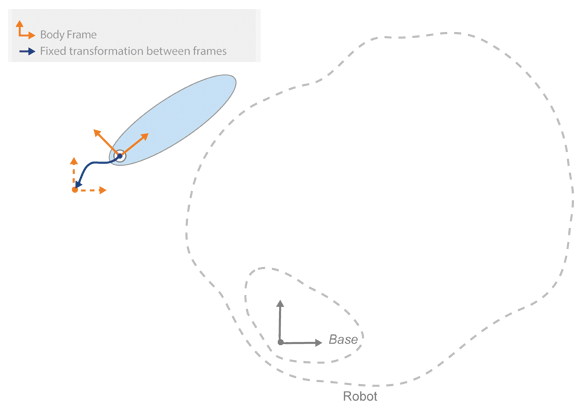

robot = rigidBodyTree

robot =   rigidBodyTree with properties:

     NumBodies: 0
        Bodies: {1×0 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×0 cell}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


    4.Agregue el primer cuerpo al árbol. Especifique que lo está adjuntando a la base del árbol. La transformación fija definida anteriormente es de la base (principal) al primer cuerpo.

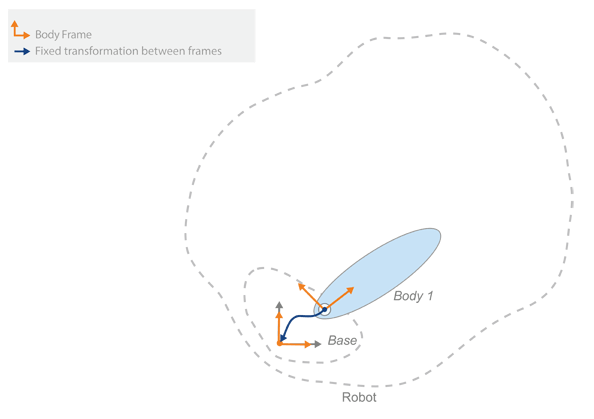

addBody(robot,body1,'base')

    5.Cree un segundo cuerpo. Defina las propiedades de este sólido y adjúntelo al primer sólido rígido. Defina la transformación en relación con el marco del cuerpo anterior.

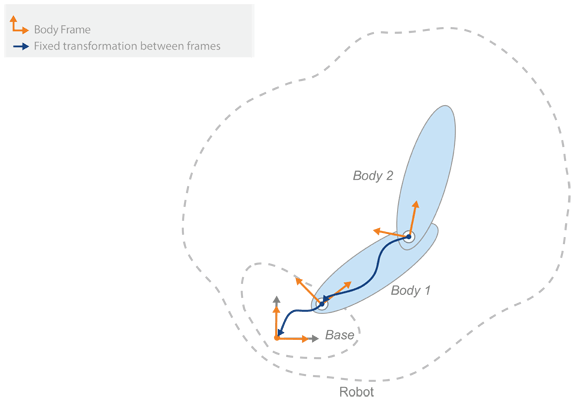

body2 = rigidBody('body2')

body2 =   rigidBody with properties:

            Name: 'body2'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


jnt2 = rigidBodyJoint('jnt2','revolute')

jnt2 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt2'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


jnt2.HomePosition = pi/6 % User defined 

jnt2 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt2'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0.5236
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform2 = trvec2tform([1, 0, 0]);% User defined 
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;
addBody(robot,body2,'body1');% Add body2 to body1

    6.Agregue otros cuerpos. Fije el cuerpo 3 y 4 al cuerpo 2.

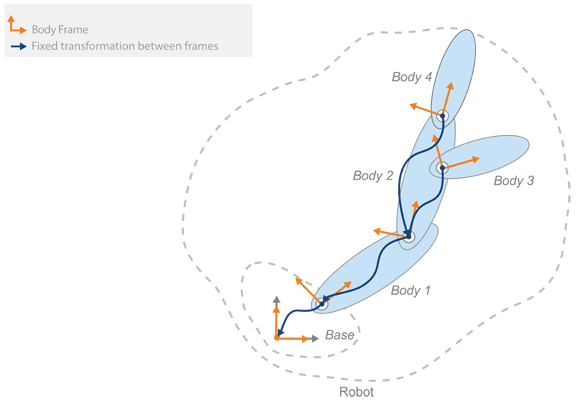

body3 = rigidBody('body3')

body3 =   rigidBody with properties:

            Name: 'body3'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


body4 = rigidBody('body4')

body4 =   rigidBody with properties:

            Name: 'body4'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


jnt3 = rigidBodyJoint('jnt3','revolute')

jnt3 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt3'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


jnt4 = rigidBodyJoint('jnt4','revolute')

jnt4 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt4'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform3 = trvec2tform([0.6, -0.1, 0])*eul2tform([-pi/2, 0, 0]); % User defined 
tform4 = trvec2tform([1, 0, 0]); % User defined
setFixedTransform(jnt3,tform3); 
setFixedTransform(jnt4,tform4); 
jnt3.HomePosition = pi/4;% User defined 
body3.Joint = jnt3

body3 =   rigidBody with properties:

            Name: 'body3'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


body4.Joint = jnt4

body4 =   rigidBody with properties:

            Name: 'body4'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


addBody(robot,body3,'body2');% Add body3 to body2 
addBody(robot,body4,'body2'); % Add body4 to body2

    7. Si tiene un efector final específico que le importa para el control, defínalo como un sólido rígido con una unión fija. Para este robot, agregue un efector final para que pueda obtener transformaciones para él `body4`

bodyEndEffector = rigidBody('endeffector')

bodyEndEffector =   rigidBody with properties:

            Name: 'endeffector'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


tform5 = trvec2tform([0.5, 0, 0])% User defined 

tform5 =     1.0000         0         0    0.5000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


setFixedTransform(bodyEndEffector.Joint,tform5)
addBody(robot,bodyEndEffector,'body4')

    8.Ahora que ha creado su robot, puede generar configuraciones de robots. Con una configuración determinada, también puede obtener una transformación entre dos marcos de cuerpo utilizando [`rigidBodyTree.getTransform`](https://la.mathworks.com/help/robotics/ref/rigidbodytree.gettransform.html). Obtenga una transformación desde el efector final hasta la base.

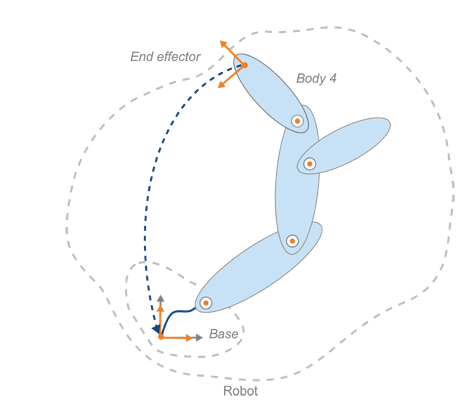

config = randomConfiguration(robot) 

config = 1×4 struct array with fields:
    JointName
    JointPosition


tform = getTransform(robot,config,'endeffector','base')

tform =     0.8530    0.5220         0    1.0304
   -0.5220    0.8530         0   -0.7663
         0         0    1.0000         0
         0         0         0    1.0000


### Robotics System Toolbox — Funciones

#### Diseño de algoritmo según el manipulador

**Modelos de robot**

*Modelos de árbol de cuerpo rígido*

importrobot		Importe el modelo de árbol de cuerpo rígido desde el archivo URDF, texto o SimscapeMultibody Modelo

loadrobot		Load rigid body tree robot model

rigidBodyTree		Crear robot estructurado en árbol

rigidBody		Create a rigid body

rigidBodyJoint		Create a joint

*Modelos de movimiento*

jointSpaceMotionModel	Model rigid body tree motion given joint-space inputs

taskSpaceMotionModel	Model rigid body tree motion given task-space reference inputs

*Cinemática*

getTransform		Get transform between body frames

randomConfiguration	Generate random configuration of robot

homeConfiguration	Get home configuration of robot

show			Mostrar modelo robot en una figura

*Dinámica*

centerOfMass		Center of mass position and Jacobian

externalForce		Compose external force matrix relative to base

forwardDynamics		Joint accelerations given joint torques and states

geometricJacobian	Jacobiano geométrico para configuración de robots

gravityTorque		Joint torques that compensate gravity

inverseDynamics		Required joint torques for given motion

massMatrix		Joint-space mass matrix

velocityProduct		Joint torques that cancel velocity-induced forces

**Cinemática Inversa**

inverseKinematics		Crear solver cinemático inverso

generalizedInverseKinematics	Create multiconstraint inverse kinematics solver

constraintAiming		Create aiming constraint for pointing at a target location

constraintJointBounds		Create constraint on joint positions of robot model

constraintCartesianBounds	Create constraint to keep body origin inside Cartesian bounds

constraintOrientationTarget	Create constraint on relative orientation of body

constraintPoseTarget		Create constraint on relative pose of body

constraintPositionTarget	Create constraint on relative position of body

**Generación de trayectoria y seguimiento**

bsplinepolytraj		Generate polynomial trajectories using B-splines

cubicpolytraj		Generate third-order polynomial trajectories

quinticpolytraj		Generate fifth-order trajectories

rottraj			Generate trajectories between orientation rotation matrices

transformtraj		Generate trajectories between two transformations

([`[tforms,vel,acc] = transformtraj(T0,TF,tInterval,tSamples)`](https://la.mathworks.com/help/robotics/ref/transformtraj.html#d123e41798)

[`[tforms,vel,acc] = transformtraj(T0,TF,tInterval,tSamples,Name,Value)`](https://la.mathworks.com/help/robotics/ref/transformtraj.html#d123e41829)`)`

Transformation velocities, returned as a 6-by-*m* matrix in m/s, where *m* is the number of points in [`tSamples`](https://la.mathworks.com/help/robotics/ref/transformtraj.html#mw_a74e1b7e-9da2-48d9-8b5e-d3f3ba69534d). The first three elements are the angular velocities, and the second three elements are the velocities in time.

trapveltraj		Generate trajectories with trapezoidal velocity profiles

**Detección de colisiones**

checkCollision	        Check if two geometries are in collision

collisionBox	        Create box collision geometry

collisionCylinder	Create collision cylinder geometry

collisionMesh        	Create convex mesh collision geometry

collisionSphere	Create sphere collision geometry

#### Coordinar transformaciones y trayectorias

**Axis-Angles**

axang2quat	Convertir rotación eje-ángulo a cuaternión

axang2rotm	Convertir la rotación del ángulo del eje en matriz de rotación

axang2tform	Convert axis-angle rotation to homogeneous transformation 

(axis-angle = eje de rotación + ángulo)

**Euler Angles**

eul2quat	Convertir ángulos de Euler en cuaternión

eul2rotm	Convertir ángulos de Euler en matriz de rotación

eul2tform	Convert Euler angles to homogeneous transformation

**Cuaterniones**

quat2axang	Convert quaternion to axis-angle rotation

quat2eul	Convertir quaternion a ángulos Euler

quat2rotm	Convertir cuaternión en matriz de rotación

quat2tform	Convert quaternion to homogeneous transformation

quaternion	Crear una matriz de cuaternión

**Matrices de rotación**

rotm2axang	Convertir matriz de rotación en rotación de ángulo de eje

rotm2eul	Convertir matriz de rotación en ángulos Euler

rotm2quat	Convertir matriz de rotación a cuaternión

rotm2tform	Convertir matriz de rotación en transformación homogénea

**Transformaciones homogéneas**

tform2axang	Convert homogeneous transformation to axis-angle rotation

tform2eul	Extract Euler angles from homogeneous transformation

tform2quat	Extract quaternion from homogeneous transformation

tform2rotm	Extract rotation matrix from homogeneous transformation

tform2trvec	Extract translation vector from homogeneous transformation

**Conversiones de coordenadas**

angdiff		Diferencia entre dos ángulos

cart2hom	Convert Cartesian coordinates to homogeneous coordinates

hom2cart	Convert homogeneous coordinates to Cartesian coordinates

trvec2tform	Convertir vector de traducción (translación?) en transformación homogénea

**Generación de trayectoria**

bsplinepolytraj		Generate polynomial trajectories using B-splines

cubicpolytraj		Generate third-order polynomial trajectories

quinticpolytraj		Generate fifth-order trajectories

rottraj	Generate 	trajectories between orientation rotation matrices

transformtraj		Generate trajectories between two transformations

trapveltraj		Generate trajectories with trapezoidal velocity profiles

**Transformaciones de trazado**

plotTransforms		Plot 3-D transforms from translations and rotations

## 4. Para realizar los puntos referentes al *Robotics Systems Toolbox (RST) *es pertinente revisar el ejemplo *Plan and Execute Task- and Joint-Space Trajectories Using KINOVA Gen3 Manipulator.*  

This example shows how to generate and simulate interpolated joint trajectories to move from an initial to a desired end-effector pose. The timing of the trajectories is based on an approximate desired end of arm tool (EOAT) speed.

    1. Load the KINOVA Gen3 rigid body tree (RBT) robot model.

robot = loadrobot('kinovaGen3','DataFormat','row','Gravity',[0 0 -9.81])

robot =   rigidBodyTree with properties:

     NumBodies: 8
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Shoulder_Link'  'HalfArm1_Link'  'HalfArm2_Link'  'ForeArm_Link'  'Wrist1_Link'  'Wrist2_Link'  'Bracelet_Link'  'EndEffector_Link'}
      BaseName: 'base_link'
       Gravity: [0 0 -9.8100]
    DataFormat: 'row'


    2. Set current robot joint configuration.

currentRobotJConfig = homeConfiguration(robot)

currentRobotJConfig =      0     0     0     0     0     0     0


    3. Get number of joints and the end-effector RBT frame.

numJoints = numel(currentRobotJConfig)

numJoints = 7

endEffector = "EndEffector_Link"

endEffector = "EndEffector_Link"

    4. Specify the trajectory time step and approximate desired tool speed.

timeStep = 0.1 % seconds

timeStep = 0.1000

toolSpeed = 0.1 % m/s

toolSpeed = 0.1000

    5. Set the initial and final end-effector pose.

jointInit = currentRobotJConfig

jointInit =      0     0     0     0     0     0     0


taskInit = getTransform(robot,jointInit,endEffector)

taskInit =     1.0000         0         0         0
         0    1.0000   -0.0000   -0.0249
         0    0.0000    1.0000    1.1854
         0         0         0    1.0000



taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]) 

taskFinal =    -1.0000         0    0.0000    0.4000
         0    1.0000         0         0
   -0.0000         0   -1.0000    0.6000
         0         0         0    1.0000


**Generate Task-Space Trajectory**

Compute task-space trajectory waypoints via interpolation.

    1. compute tool traveling distance.

distance = norm(tform2trvec(taskInit)-tform2trvec(taskFinal))

distance = 0.7094

    2. define trajectory times based on traveling distance and desired tool speed.

initTime = 0

initTime = 0

finalTime = (distance/toolSpeed) - initTime

finalTime = 7.0943

trajTimes = initTime:timeStep:finalTime

trajTimes =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


timeInterval = [trajTimes(1); trajTimes(end)]

timeInterval =      0
     7


    3. Interpolate between `taskInit` and `taskFinal` to compute intermediate task-space waypoints.

- **Task space** means the waypoints and interpolation are on the Cartesian pose (position and orientation) of a specific location on the manipulator – usually the end effector.

- **Joint space** means the waypoints and interpolation are directly on the joint positions (angles or displacements, depending on the type of joint)

- 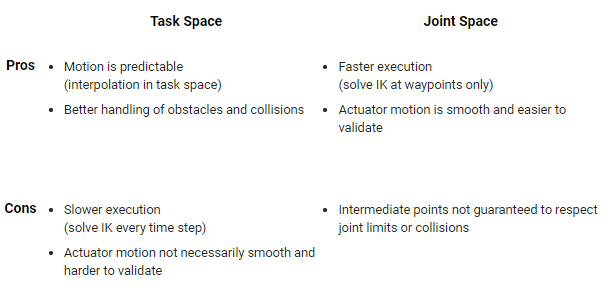

[taskWaypoints,taskVelocities] = transformtraj(taskInit,taskFinal,timeInterval,trajTimes)

taskWaypoints = taskWaypoints(:,:,1) =

    1.0000         0         0         0
         0    1.0000   -0.0000   -0.0249
         0    0.0000    1.0000    1.1854
         0         0         0    1.0000


taskWaypoints(:,:,2) =

    0.9990    0.0000    0.0449    0.0057
    0.0000    1.0000   -0.0000   -0.0245
   -0.0449    0.0000    0.9990    1.1770
         0         0         0    1.0000


taskWaypoints(:,:,3) =

    0.9960    0.0000    0.0896    0.0114
    0.0000    1.0000   -0.0000   -0.0241
   -0.0896    0.0000    0.9960    1.1687
         0         0         0    1.0000


taskWaypoints(:,:,4) =

    0.9909    0.0000    0.1342    0.0171
    0.0000    1.0000   -0.0000   -0.0238
   -0.1342    0.0000    0.9909    1.1603
         0         0         0    1.0000


taskWaypoints(:,:,5) =

    0.9839    0.0000    0.1786    0.0229
    0.0000    1.0000   -0.0000   -0.0234
   -0.1786    0.0000    0.9839    1.1519
         0         0         0    1.0000


taskWaypoints(:,:,6) =

    0.9749

taskVelocities =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488  

**Control Task-Space Motion**

    1. Create a joint space motion model for PD control on the joints. The `taskSpaceMotionModel` object models the motion of a rigid body tree model under task-space proportional-derivative control.

tsMotionModel = taskSpaceMotionModel('RigidBodyTree',robot,'EndEffectorName','EndEffector_Link')

tsMotionModel =   taskSpaceMotionModel with properties:

      RigidBodyTree: [1×1 rigidBodyTree]
    EndEffectorName: 'EndEffector_Link'
       JointDamping: [1 1 1 1 1 1 1]
         MotionType: 'PDControl'
                 Kp: [6×6 double]
                 Kd: [6×6 double]


    2. Set the proportional and derivative gains on orientation to zero, so that controlled behavior just follows the reference positions:

- `Kp` **—** **Proportional gain for PD Control (**`500*eye(6)` (default) | 6-by-6 matrix)

- `Kd` **—** **Derivative gain for PD control (**`100*eye(6)` (default) | 6-by-6 matrix)

tsMotionModel.Kp(1:3,1:3) = 0

tsMotionModel =   taskSpaceMotionModel with properties:

      RigidBodyTree: [1×1 rigidBodyTree]
    EndEffectorName: 'EndEffector_Link'
       JointDamping: [1 1 1 1 1 1 1]
         MotionType: 'PDControl'
                 Kp: [6×6 double]
                 Kd: [6×6 double]


tsMotionModel.Kd(1:3,1:3) = 0

tsMotionModel =   taskSpaceMotionModel with properties:

      RigidBodyTree: [1×1 rigidBodyTree]
    EndEffectorName: 'EndEffector_Link'
       JointDamping: [1 1 1 1 1 1 1]
         MotionType: 'PDControl'
                 Kp: [6×6 double]
                 Kd: [6×6 double]


    3. Define the initial states (joint positions and velocities).

q0 = currentRobotJConfig

q0 =      0     0     0     0     0     0     0


qd0 = zeros(size(q0))

qd0 =      0     0     0     0     0     0     0


    4. Use `ode15s` to simulate the robot motion. For this problem, the closed-loop system is stiff, meaning that there is a difference in scaling somewhere in the problem. As a result, the integrator is sometimes forced to take exceedingly small steps, and a non-stiff ODE solver such as `ode45` will take much longer to solve the same problem. For more information, refer to [Choose an ODE Solver](https://la.mathworks.com/help/matlab/math/choose-an-ode-solver.html) and [Solve Stiff ODEs](https://la.mathworks.com/help/matlab/math/solve-stiff-odes.html) in the documentation.

Since the reference state changes at each instant, a wrapper function is required to update the interpolated trajectory input to the state derivative at each instant. Therefore, an example helper function is passed as the function handle to the ODE solver. The resultant manipulator states are output in `stateTask`.

y = exampleHelperTimeBasedTaskInputs(tsMotionModel,timeInterval,taskInit,taskFinal,t,state)

Unrecognized function or variable 't'.

%[tTask,stateTask] = ode15s(@(t,state),y ,timeInterval,[q0; qd0])
